%% Linear Algebra Midterm Practice Problems
% This is a set of practice problems to help you prepare for your Linear Algebra midterm.
% The problems cover vectors, matrices, and their operations and applications from your lecture notes.

%% Section 1: Vectors and Basic Operations

%% Problem 1.1: Vector Operations
% Given vectors u = [2, -1, 3] and v = [4, 0, -2]:
% a) Calculate u + v
% b) Calculate 3u - 2v
% c) Find the dot product of u and v
% d) Find the cross product of u and v
% e) Calculate the L1 norm (Manhattan norm) and L2 norm (Euclidean norm) of vector u

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Define the vectors
u = [2, -1, 3];
v = [4, 0, -2];

% a) Calculate u + v
result_a = u + v;

% b) Calculate 3u - 2v
result_b = 3*u - 2*v;

% c) Find the dot product of u and v
result_c = dot(u, v);

% d) Find the cross product of u and v
result_d = cross(u, v);

% e) Calculate the L1 norm and L2 norm of vector u
L1_norm = norm(u, 1);
L2_norm = norm(u, 2);

% Display results
disp('a) u + v = '); disp(result_a);
disp('b) 3u - 2v = '); disp(result_b);
disp('c) u·v = '); disp(result_c);
disp('d) u×v = '); disp(result_d);
disp('e) L1 norm of u = '); disp(L1_norm);
disp('   L2 norm of u = '); disp(L2_norm);

%% Problem 1.2: Vector Applications
% a) Convert vector w = [3, 5, 2] into a unit vector in the same direction.
% b) Two vectors a = [1, 3, 2] and b = [2, -1, 4] form a plane. Find the normal vector to this plane.
% c) Write the equation of this plane in the form ax + by + cz = d, where [a, b, c] is the normal vector.

% Clear workspace
clear;

% a) Convert w to a unit vector
w = [3, 5, 2];
unit_w = w / norm(w,2);
sum(unit_w.^2)

% b) Find the normal vector to the plane formed by a and b
a = [1, 3, 2];
b = [2, -1, 4];
normal_vector = cross(a,b);

% c) Write the equation of the plane
% Choose a point on the plane (for example, using a)
point = a;
% Calculate d in ax + by + cz = d
d = -dot(point, normal_vector);

% Display results
disp('a) Unit vector in direction of w = '); disp(unit_w);
disp('b) Normal vector to plane = '); disp(normal_vector);
disp(['c) Equation of plane: ' num2str(normal_vector(1)) 'x + ' ...
      num2str(normal_vector(2)) 'y + ' num2str(normal_vector(3)) 'z = ' num2str(d)]);

% Visualization of the plane
figure;
[x, y] = meshgrid(-5:0.5:5, -5:0.5:5);
z = (-d - normal_vector(1)*x - normal_vector(2)*y) / normal_vector(3);
mesh(x, y, z);
hold on;
quiver3(0, 0, 0, a(1), a(2), a(3), 'r', 'LineWidth', 2, 'AutoScale', 'off', 'MaxHeadSize', 1);
quiver3(0, 0, 0, b(1), b(2), b(3), 'b', 'LineWidth', 2, 'AutoScale', 'off', 'MaxHeadSize', 1);
quiver3(0, 0, 0, normal_vector(1), normal_vector(2), normal_vector(3), 'g', 'LineWidth', 2, 'AutoScale', 'off', 'MaxHeadSize', 1);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Plane Formed by Two Vectors');
legend('Plane', 'Vector a', 'Vector b', 'Normal Vector');
grid on;
view(45, 30);

%% Section 2: Matrices and Basic Operations

%% Problem 2.1: Matrix Construction and Operations
% a) Create a 3×3 diagonal matrix with elements [4, -1, 7] on the diagonal.
% b) Create a 3×3 identity matrix and multiply it by 5.
% c) Given matrices A = [1, 2; 3, 4] and B = [5, 6; 7, 8], calculate:
%    i) A + B
%    ii) A - B
%    iii) The Hadamard product of A and B (element-wise multiplication)
%    iv) The matrix product AB
%    v) The matrix product BA

% Clear workspace
clear;

% a) Create a 3×3 diagonal matrix
diag_elements = [4, -1, 7];
diag_matrix = diag(diag_elements);

% b) Create a 3×3 identity matrix and multiply it by 5
scaled_identity = eye(3) * 5;

% c) Matrix operations with A and B
A = [1, 2; 3, 4];
B = [5, 6; 7, 8];

% i) A + B
sum_matrix = A + B;

% ii) A - B
diff_matrix = A - B;

% iii) Hadamard product of A and B
hadamard_product = A.*B;

% iv) Matrix product AB
product_AB = A*B;

% v) Matrix product BA
product_BA = B*A;

% Display results
disp('a) Diagonal matrix:'); disp(diag_matrix);
disp('b) Scaled identity matrix:'); disp(scaled_identity);
disp('c-i) A + B:'); disp(sum_matrix);
disp('c-ii) A - B:'); disp(diff_matrix);
disp('c-iii) Hadamard product:'); disp(hadamard_product);
disp('c-iv) Matrix product AB:'); disp(product_AB);
disp('c-v) Matrix product BA:'); disp(product_BA);

%% Problem 2.2: Matrix Properties
% For the matrix C = [2, 1, 3; 0, -1, 4; 2, 5, -2]:
% a) Calculate the determinant of C.
% b) Find the transpose of C.
% c) Extract the upper triangular part of C.
% d) Extract the lower triangular part of C.
% e) Extract the diagonal elements of C as a vector.

% Clear workspace
clear;

% Define matrix C
C = [2, 1, 3; 0, -1, 4; 2, 5, -2];

% a) Calculate the determinant of C
det_C = det(C);

% b) Find the transpose of C
trans_C = C';

% c) Extract the upper triangular part of C
upper_C = triu(C);

% d) Extract the lower triangular part of C
lower_C = tril(C);

% e) Extract the diagonal elements of C as a vector
diag_C = diag(C);

% Display results
disp('Matrix C:'); disp(C);
disp('a) Determinant of C = '); disp(det_C);
disp('b) Transpose of C:'); disp(trans_C);
disp('c) Upper triangular part of C:'); disp(upper_C);
disp('d) Lower triangular part of C:'); disp(lower_C);
disp('e) Diagonal elements of C:'); disp(diag_C);

% Visualization of the matrix and its properties
figure;

% Original matrix
subplot(2, 2, 1);
imagesc(C);
colorbar;
title('Original Matrix C');
axis square;

% Upper triangular
subplot(2, 2, 2);
imagesc(upper_C);
colorbar;
title('Upper Triangular');
axis square;

% Lower triangular
subplot(2, 2, 3);
imagesc(lower_C);
colorbar;
title('Lower Triangular');
axis square;

% Diagonal
subplot(2, 2, 4);
imagesc(diag(diag_C));
colorbar;
title('Diagonal Elements');
axis square;


%% Section 3: Matrix Concepts

%% Problem 3.1: Matrix Spaces
% Consider the matrix D = [1, 3, 2; 4, 1, 5]:
% a) Determine the rank of D.
% b) Find a basis for the column space of D.
% c) Find a basis for the null space of D.

% Clear workspace
clear;

% Define matrix D
D = [1, 3, 2; 4, 1, 5];

% a) Determine the rank of D
rank_D = rank(D);

% b) Find a basis for the column space of D
% You can use the rref function or examine the columns directly
[~, pivot_columns] = rref(D);
column_space_basis = D(:, pivot_columns);

% c) Find a basis for the null space of D
null_space_basis = null(D);

% Display results
disp('Matrix D:'); disp(D);
disp('a) Rank of D = '); disp(rank_D);
disp('b) Basis for column space of D:'); disp(column_space_basis);
disp('c) Basis for null space of D:'); disp(null_space_basis);


%% Problem 3.2: Matrix Norms and Traces
% For the matrix E = [3, -1, 2; 4, 0, -2; 1, 5, 3]:
% a) Calculate the Frobenius norm of E.
% b) Calculate the trace of E.
% c) Calculate the trace of E² (E squared).

% Clear workspace
clear;

% Define matrix E
E = [3, -1, 2; 4, 0, -2; 1, 5, 3];

% a) Calculate the Frobenius norm of E
frob_norm = norm(E, 'fro');

% b) Calculate the trace of E
trace_E = trace(E);

% c) Calculate the trace of E²
E_squared = E' * E;
trace_E_squared = trace(E_squared);

% Display results
disp('Matrix E:'); disp(E);
disp('a) Frobenius norm of E = '); disp(frob_norm);
disp('b) Trace of E = '); disp(trace_E);
disp('c) E squared:'); disp(E_squared);
disp('   Trace of ET*E = '); disp(trace_E_squared);


%% Section 4: Matrix Transformations

%% Problem 4.1: Matrix as a Transformation
% Let T = [0, 1; -1, 0] be a transformation matrix.
% a) Apply this transformation to the vector v = [3, 2].
% b) Describe geometrically what this transformation does to vectors in R².
% c) Draw a circle of points and show how T transforms them.

% Clear workspace
clear;

% Define transformation matrix T and vector v
T = [0, 1; -1, 0];
v = [3; 2];  % Column vector for matrix multiplication

% a) Apply the transformation to v
transformed_v = T*v;

% Display results
disp('Transformation matrix T:'); disp(T);
disp('Vector v:'); disp(v);
disp('a) Transformed vector T·v:'); disp(transformed_v);

% b) Describe geometrically what this transformation does
disp('b) Geometric interpretation:');
disp('   This transformation rotates vectors counterclockwise by 90 degrees.');

% c) Visualize the transformation of a circle of points
theta = linspace(0, 2*pi, 100);
original_points = [cos(theta); sin(theta)];
transformed_points = T*original_points;

% Visualization
figure;
plot(original_points(1,:), original_points(2,:), 'b-', 'LineWidth', 2);
hold on;
plot(transformed_points(1,:), transformed_points(2,:), 'r-', 'LineWidth', 2);
quiver(0, 0, v(1), v(2), 'b', 'LineWidth', 2, 'AutoScale', 'off', 'MaxHeadSize', 0.5);
quiver(0, 0, transformed_v(1), transformed_v(2), 'r', 'LineWidth', 2, 'AutoScale', 'off', 'MaxHeadSize', 0.5);
axis equal;
xlabel('x');
ylabel('y');
title('Transformation T applied to a unit circle and vector v');
legend('Original Circle', 'Transformed Circle', 'Vector v', 'Transformed Vector T·v');
grid on;


%% Problem 4.2: Correlation and Covariance !!!!!!!!!!!!!!!!!!!!!!!!
% Given two data vectors:
% x = [1, 3, 5, 7, 9]
% y = [2, 4, 5, 8, 10]
%
% a) Calculate the covariance between x and y.
% b) Calculate the correlation coefficient between x and y.

% Clear workspace
clear;

% Define data vectors
x = [1, 3, 5, 7, 9];
y = [2, 4, 5, 8, 10];

% a) Calculate the covariance between x and y manually
% Step 1: Calculate the means
mean_x = mean(x);
mean_y = mean(y);

% Step 2: Center the data
x_centered = x - mean_x;
y_centered = y - mean_y;

% Step 3: Calculate the covariance
% covariance_xy = cov(x_centered, y_centered);
covariance_xy = sum(x_centered .* y_centered)/(length(x)-1);

% b) Calculate the correlation coefficient
variance_x = sum(diag(x_centered'*x_centered))/(length(x)-1)

variance_x = 10

% variance_y = diag(y_centered'*y_centered)/(length(y)-1);
% variance_x = sum(x_centered.^2) / (length(x) - 1)
variance_y = sum(y_centered.^2) / (length(y) - 1)

variance_y = 10.2000

% correlation_xy = covariance_xy / sqrt((variance_x) * std(variance_y));
correlation_xy = covariance_xy / sqrt(variance_x * variance_y)

correlation_xy = 0.9901



% Using built-in functions to verify results
builtin_cov = cov(x, y);
builtin_corr = corrcoef(x, y);

% Display results
disp('Data vector x:'); disp(x);

Data vector x:
     1     3     5     7     9



disp('Data vector y:'); disp(y);

Data vector y:
     2     4     5     8    10



disp('a) Covariance between x and y = '); disp(covariance_xy);

a) Covariance between x and y = 
    10



disp('   Verification using cov():'); disp(builtin_cov);

   Verification using cov():
   10.0000   10.0000
   10.0000   10.2000



disp('b) Correlation coefficient between x and y = '); disp(correlation_xy);

b) Correlation coefficient between x and y = 
    0.9901



disp('   Verification using corrcoef():'); disp(builtin_corr);

   Verification using corrcoef():
    1.0000    0.9901
    0.9901    1.0000



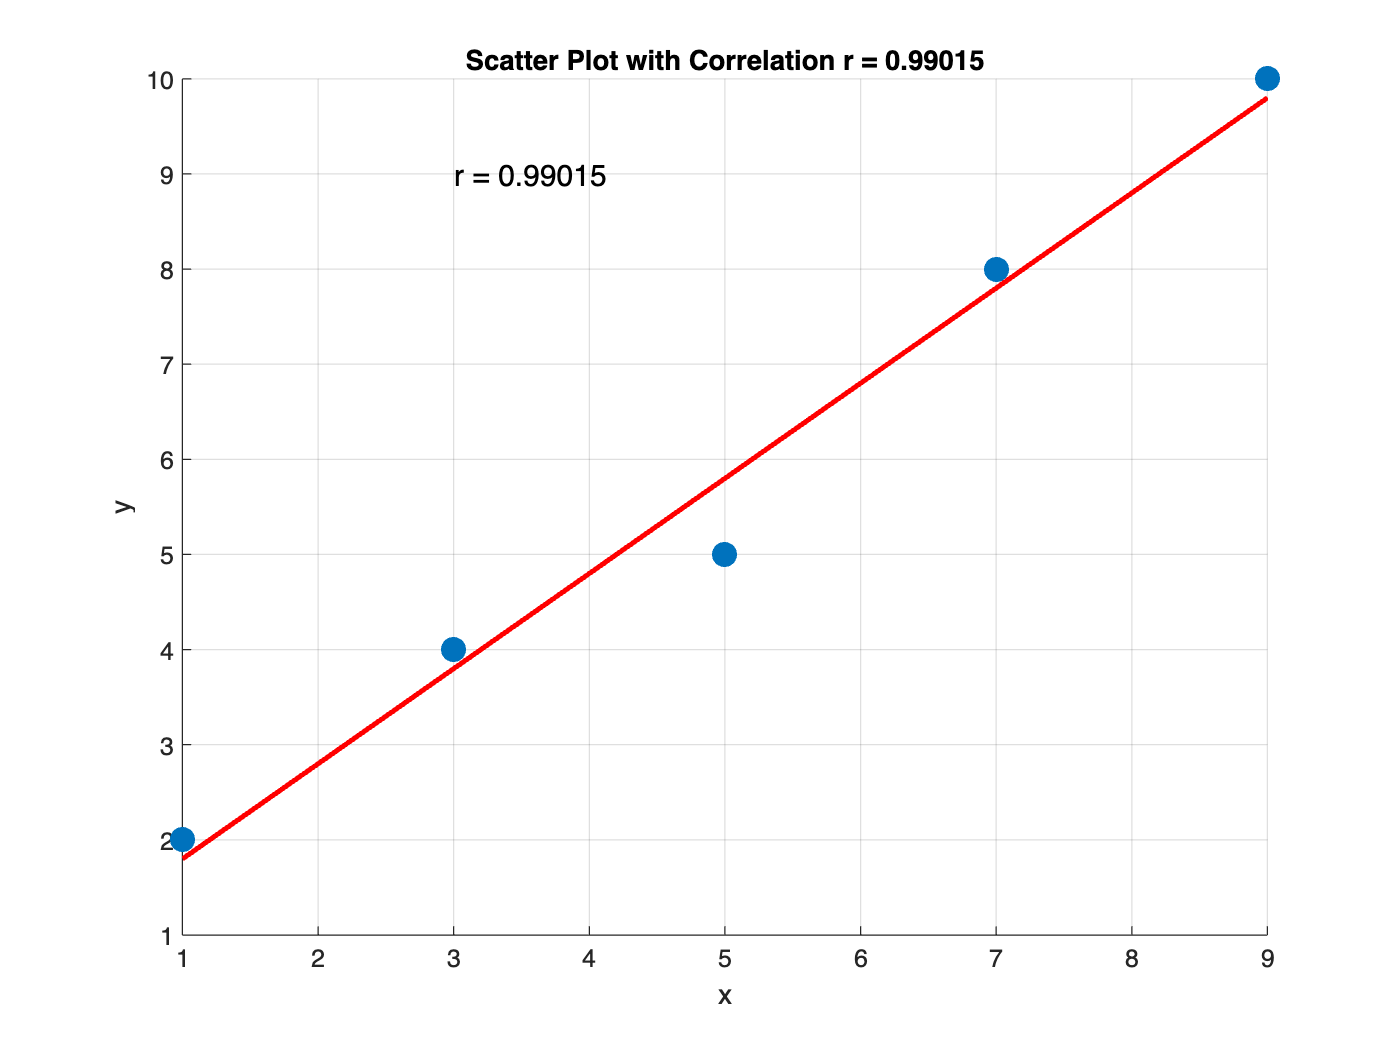


% Scatter plot of the data
figure;
scatter(x, y, 100, 'filled');
hold on;
% Add regression line
p = polyfit(x, y, 1);
x_line = linspace(min(x), max(x), 100);
y_line = polyval(p, x_line);
plot(x_line, y_line, 'r-', 'LineWidth', 2);
title(['Scatter Plot with Correlation r = ' num2str(correlation_xy)]);
xlabel('x');
ylabel('y');
grid on;
text(3, 9, ['r = ' num2str(correlation_xy)], 'FontSize', 12);


%% Section 5: Matrix Inverses

%% Problem 5.1: Computing Inverses
% For the matrix F = [2, 1; 3, 2]:
% a) Calculate the determinant of F to determine if it's invertible.
% b) If invertible, calculate the inverse of F using the formula for 2×2 matrices.
% c) Verify your answer by checking that F · F⁻¹ = I (identity matrix).

% Clear workspace
clear;

% Define matrix F
F = [2, 1; 3, 2];

% a) Calculate the determinant of F
det_F = det(F);

% b) Calculate the inverse of F (if invertible)
if det_F ~= 0
    % For a 2×2 matrix [a, b; c, d], the inverse is [d, -b; -c, a]/det
    a = F(1,1); b = F(1,2); c = F(2,1); d = F(2,2);
    F_inv_manual = (1/det_F) * [d -b;
                             -c a];

    % Using the built-in inv function to verify
    F_inv_builtin = inv(F);
else
    disp('Matrix F is not invertible');
end

% c) Verify that F · F⁻¹ = I
identity_check = F * F_inv_manual;

% Display results
disp('Matrix F:'); disp(F);

Matrix F:
     2     1
     3     2



disp('a) Determinant of F = '); disp(det_F);

a) Determinant of F = 
    1.0000



if det_F ~= 0
    disp('b) Inverse of F (manual calculation):'); disp(F_inv_manual);
    disp('   Inverse of F (using inv()):'); disp(F_inv_builtin);
    disp('c) F · F⁻¹ = '); disp(identity_check);
    if norm(identity_check - eye(size(F))) < 1e-10
        disp('   Verification successful: F · F⁻¹ = I');
    else
        disp('   Verification failed');
    end
end

b) Inverse of F (manual calculation):
    2.0000   -1.0000
   -3.0000    2.0000



   Inverse of F (using inv()):
    2.0000   -1.0000
   -3.0000    2.0000



c) F · F⁻¹ = 
     1     0
     0     1



   Verification successful: F · F⁻¹ = I



%% Problem 5.2: Left Inverse
% For the matrix G = [1, 2, 3; 4, 5, 6]:
% a) Calculate G^T (transpose of G).
% b) Calculate G^T · G.
% c) Calculate (G^T · G)^(-1).
% d) Find the left inverse of G using the formula L = (G^T · G)^(-1) · G^T.
% e) Verify your answer by checking that L · G = I.

% Clear workspace
clear;

% Define matrix G
G = [1, 2, 3; 4, 5, 6;7 3 1; 5 4 3];

% a) Calculate G^T
G_trans = G';

% b) Calculate G^T · G
G_trans_G = G_trans * G; 

% c) Calculate (G^T · G)^(-1)
G_trans_G_inv = inv(G_trans_G);

% d) Find the left inverse of G
L = G_trans_G_inv * G_trans;

% e) Verify that L · G = I
identity_check = L * G;

% Display results
disp('Matrix G:'); disp(G);

Matrix G:
     1     2     3
     4     5     6
     7     3     1
     5     4     3



disp('a) G^T:'); disp(G_trans);

a) G^T:
     1     4     7     5
     2     5     3     4
     3     6     1     3



disp('b) G^T · G:'); disp(G_trans_G);

b) G^T · G:
    91    63    49
    63    54    51
    49    51    55



disp('c) (G^T · G)^(-1):'); disp(G_trans_G_inv);

c) (G^T · G)^(-1):
    0.7321   -1.9167    1.1250
   -1.9167    5.1667   -3.0833
    1.1250   -3.0833    1.8750



disp('d) Left inverse L:'); disp(L);

d) Left inverse L:
    0.2738    0.0952    0.5000   -0.6310
   -0.8333   -0.3333   -1.0000    1.8333
    0.5833    0.3333    0.5000   -1.0833



disp('e) L · G = '); disp(identity_check);

e) L · G = 
    1.0000   -0.0000   -0.0000
   -0.0000    1.0000    0.0000
    0.0000   -0.0000    1.0000



if norm(identity_check - eye(size(G, 2))) < 1e-10
    disp('   Verification successful: L · G = I');
else
    disp('   Verification failed');
end

   Verification successful: L · G = I



%% Section 6: App%% Problem 6.1: k-means Clustering
% Given a set of 2D data points:
% data = {(1,2), (2,1), (5,4), (4,5), (8,1), (7,2)}
%
% a) Initialize 2 centroids at (2,1) and (5,4).
% b) Calculate the Euclidean distance from each point to each centroid.
% c) Assign each point to the closest centroid.
% d) Recalculate the centroids as the mean of the assigned points.
% e) Repeat steps b-d for one more iteration.

% Clear workspace
clear;

% Define the data
data = [1, 2; 2, 1; 5, 4; 4, 5; 8, 1; 7, 2];

% a) Initialize centroids
centroids = [2, 1; 5, 4];

% b) Calculate distances from each point to each centroid (first iteration)
distances = zeros(size(data, 1), size(centroids, 1));
for i = 1:size(data, 1)
    for j = 1:size(centroids, 1)
        distances(i, j) = sqrt(sum((data(i,:) - centroids(j,:)).^2));
    end
end

% c) Assign each point to the closest centroid (first iteration)
[~, assignments] = min(distances, [], 2);

% d) Recalculate centroids (first iteration)
new_centroids = zeros(size(centroids));
for i = 1:size(centroids, 1)
    cluster_points = data(assignments == i, :);
    if ~isempty(cluster_points)
        new_centroids(i, :) = mean(cluster_points);
    else
        new_centroids(i, :) = centroids(i, :); % Keep old centroid if no points assigned
    end
end

% e) Repeat steps b-d for one more iteration
old_centroids = new_centroids;

% Calculate distances again (second iteration)
distances2 = zeros(size(data, 1), size(old_centroids, 1));
for i = 1:size(data, 1)
    for j = 1:size(old_centroids, 1)
        distances2(i, j) = sqrt(sum((data(i,:) - old_centroids(j,:)).^2));
    end
end

% Assign each point to the closest centroid (second iteration)
[~, assignments2] = min(distances2, [], 2);

% Recalculate centroids (second iteration)
final_centroids = zeros(size(old_centroids));
for i = 1:size(old_centroids, 1)
    cluster_points = data(assignments2 == i, :);
    if ~isempty(cluster_points)
        final_centroids(i, :) = mean(cluster_points);
    else
        final_centroids(i, :) = old_centroids(i, :);
    end
end

% Display results
disp('Data points:'); disp(data);

Data points:
     1     2
     2     1
     5     4
     4     5
     8     1
     7     2



disp('a) Initial centroids:'); disp(centroids);

a) Initial centroids:
     2     1
     5     4



disp('b) Distances (first iteration):'); disp(distances);

b) Distances (first iteration):
    1.4142    4.4721
         0    4.2426
    4.2426         0
    4.4721    1.4142
    6.0000    4.2426
    5.0990    2.8284



disp('c) Assignments (first iteration):'); disp(assignments);

c) Assignments (first iteration):
     1
     1
     2
     2
     2
     2



disp('d) Updated centroids (first iteration):'); disp(new_centroids);

d) Updated centroids (first iteration):
    1.5000    1.5000
    6.0000    3.0000



disp('e) Distances (second iteration):'); disp(distances2);

e) Distances (second iteration):
    0.7071    5.0990
    0.7071    4.4721
    4.3012    1.4142
    4.3012    2.8284
    6.5192    2.8284
    5.5227    1.4142



disp('   Assignments (second iteration):'); disp(assignments2);

   Assignments (second iteration):
     1
     1
     2
     2
     2
     2



disp('   Final centroids:'); disp(final_centroids);

   Final centroids:
    1.5000    1.5000
    6.0000    3.0000



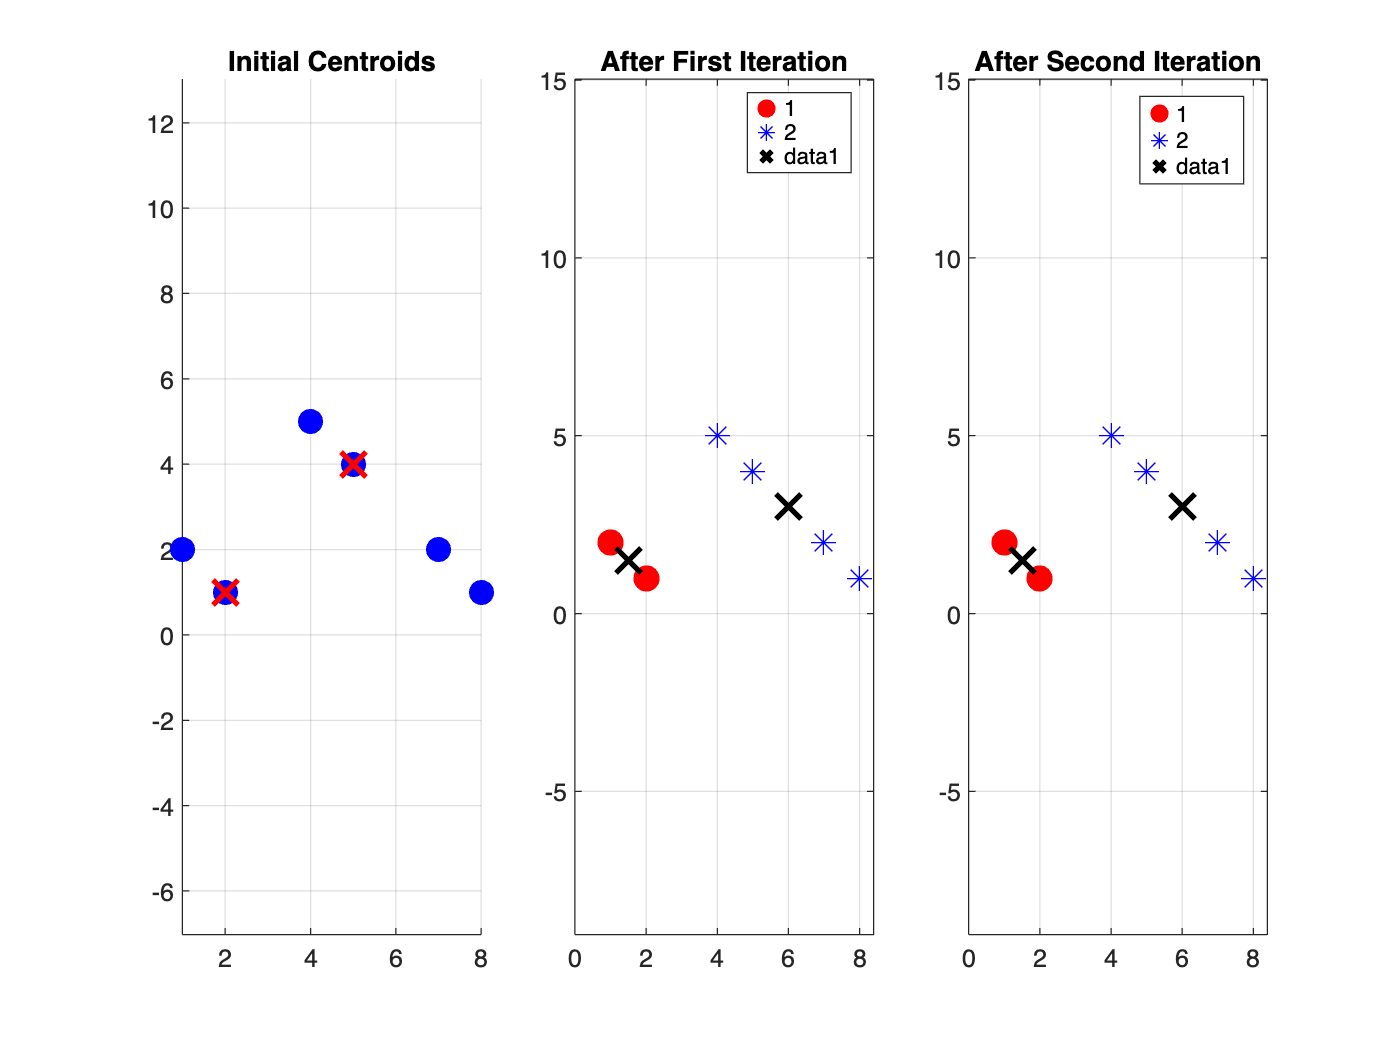


% Visualization of the clustering
figure;

% Plot the original data and initial centroids
subplot(1, 3, 1);
scatter(data(:,1), data(:,2), 100, 'b', 'filled');
hold on;
scatter(centroids(:,1), centroids(:,2), 200, 'r', 'x', 'LineWidth', 2);
title('Initial Centroids');
axis equal;
grid on;

% Plot after first iteration
subplot(1, 3, 2);
gscatter(data(:,1), data(:,2), assignments, 'rb', 'o*', 10, 'filled');
hold on;
scatter(new_centroids(:,1), new_centroids(:,2), 200, 'k', 'x', 'LineWidth', 2);
title('After First Iteration');
axis equal;
grid on;

% Plot after second iteration
subplot(1, 3, 3);
gscatter(data(:,1), data(:,2), assignments2, 'rb', 'o*', 10, 'filled');
hold on;
scatter(final_centroids(:,1), final_centroids(:,2), 200, 'k', 'x', 'LineWidth', 2);
title('After Second Iteration');
axis equal;
grid on;


%% Problem 6.2: Edge Detection
% Consider the 1D signal: [0, 0, 0, 10, 10, 10, 0, 0, 0]
% Apply the edge detection kernel [-1, 1] to this signal and show the resulting feature map.

% Clear workspace
clear;

% Define the 1D signal
signal = [0, 0, 0, 10, 10, 10, 0, 0, 0];

% Define the edge detection kernel
kernel = [-1, 1];

% Apply the edge detection kernel to the signal
feature_map = zeros(1, length(signal) - 1);
for i = 1:(length(signal) - 1)
    feature_map(i) = dot(kernel, signal(i:i+1));
end

% Display results
disp('1D Signal:'); disp(signal);

1D Signal:
     0     0     0    10    10    10     0     0     0



disp('Edge Detection Kernel:'); disp(kernel);

Edge Detection Kernel:
    -1     1



disp('Feature Map:'); disp(feature_map);

Feature Map:
     0     0    10     0     0   -10     0     0



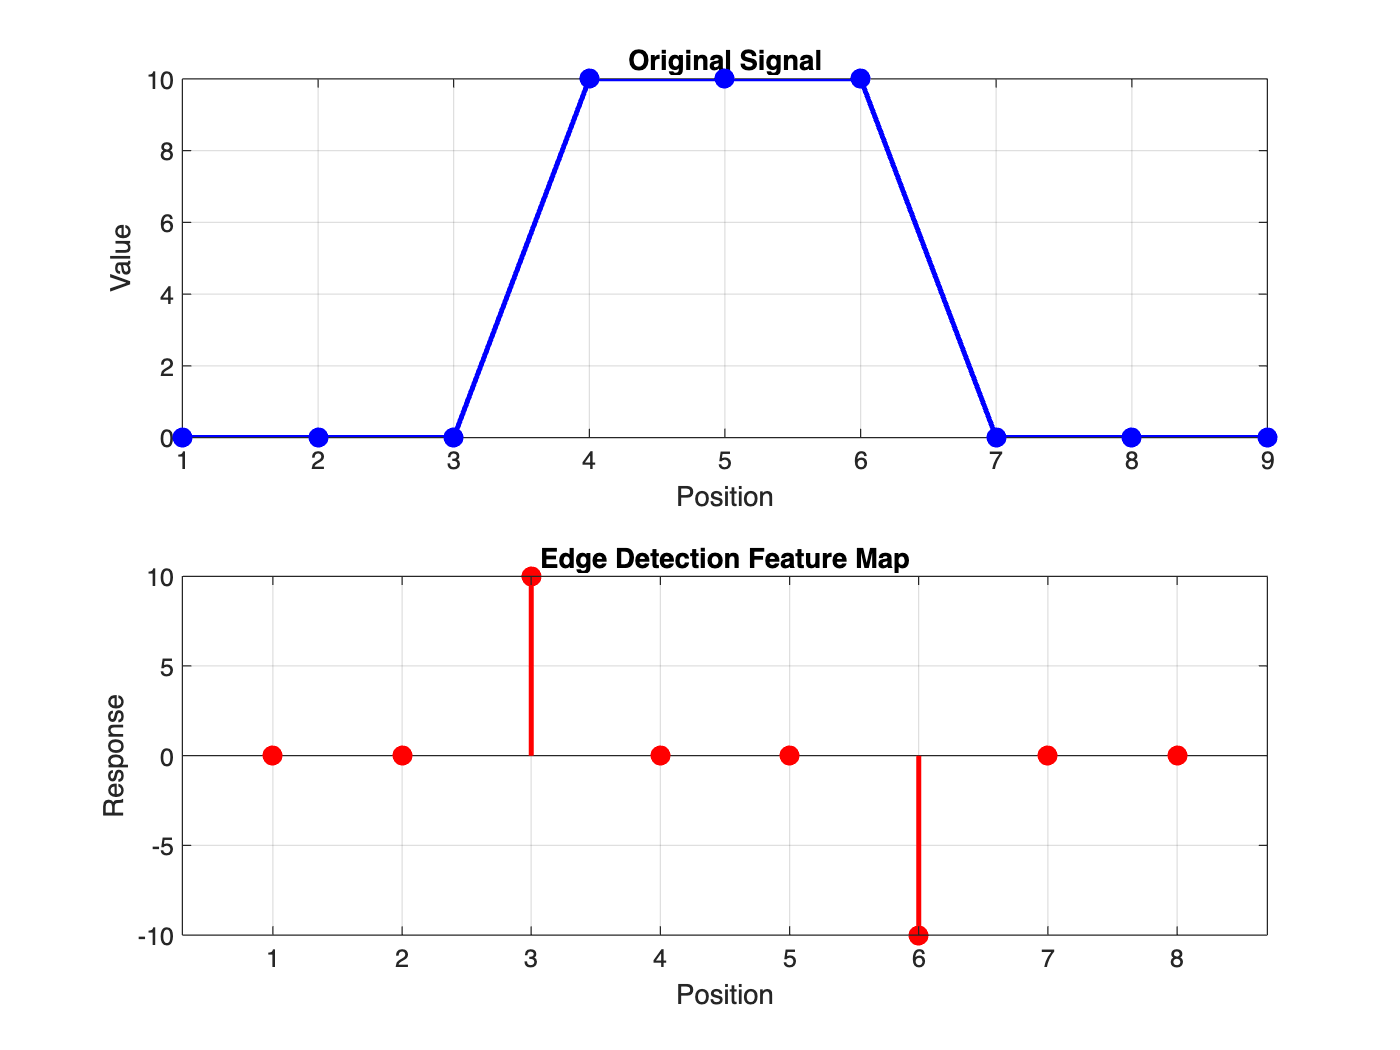


% Visualization
figure;
subplot(2, 1, 1);
plot(signal, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
title('Original Signal');
xlabel('Position');
ylabel('Value');
grid on;

subplot(2, 1, 2);
stem(feature_map, 'r', 'filled', 'LineWidth', 2);
title('Edge Detection Feature Map');
xlabel('Position');
ylabel('Response');
grid on;

% %% Problem 6.2: Edge Detection
% Consider the 1D signal: [0, 0, 0, 10, 10, 10, 0, 0, 0]
% Apply the edge detection kernel [-1, 1] to this signal and show the resulting feature map.

% Clear workspace
clear;

% Define the 1D signal
signal = [0, 0, 0, 10, 10, 10, 0, 0, 0];

% Define the edge detection kernel
kernel = [-1, 1];

% Apply the edge detection kernel to the signal
feature_map = zeros(1, length(signal) - 1);
for i = 1:(length(signal) - 1)
    feature_map(i) = dot(kernel, signal(i:i+1));
end

% Display results
disp('1D Signal:'); disp(signal);

1D Signal:
     0     0     0    10    10    10     0     0     0



disp('Edge Detection Kernel:'); disp(kernel);

Edge Detection Kernel:
    -1     1



disp('Feature Map:'); disp(feature_map);

Feature Map:
     0     0    10     0     0   -10     0     0




% Visualization
figure;
subplot(2, 1, 1);
plot(signal, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
title('Original Signal');
xlabel('Position');
ylabel('Value');
grid on;

subplot(2, 1, 2);
stem(feature_map, 'r', 'filled', 'LineWidth', 2);
title('Edge Detection Feature Map');
xlabel('Position');
ylabel('Response');
grid on;

% 

%% Section 7: Computational Challenges

%% Problem 7.1: Matrix Creation with Specified Rank
% Write the steps to create a 4×6 matrix with rank 3. Explain your approach.

% Clear workspace
clear;

% Create a 4×6 matrix with rank 3
% Approach: Multiply a 4×3 matrix by a 3×6 matrix
A = randn(4, 3);
B = randn(3, 6);
C = A * B;

% Check the rank of the created matrix
rank_C = rank(C);

% Display results
disp('4×6 Matrix C with rank 3:'); disp(C);

4×6 Matrix C with rank 3:
    2.9276    5.1810    3.6122    5.4130    3.1938   -2.8867
    3.3922    3.9121    2.5904    1.3625    1.5566   -3.1211
   -2.5761   -1.4941   -4.7037    0.2159   -2.5342    1.6207
    2.7730    4.3019    3.7383    4.1523    2.9821   -2.5503



disp('Rank of C = '); disp(rank_C);

Rank of C = 
     3



disp('Explanation of approach:');

Explanation of approach:


disp('I created a 4×6 matrix with rank 3 by multiplying a 4×3 matrix with a 3×6 matrix.');

I created a 4×6 matrix with rank 3 by multiplying a 4×3 matrix with a 3×6 matrix.


disp('The rank of the product cannot exceed the minimum of the ranks of the factors.');

The rank of the product cannot exceed the minimum of the ranks of the factors.


disp('Since both factor matrices have full rank 3, the product has rank 3.');

Since both factor matrices have full rank 3, the product has rank 3.



%% Problem 7.2: Geometric Transformation
% Define a transformation matrix T = [cos(π/4), -sin(π/4); sin(π/4), cos(π/4)].
% a) What geometric transformation does this matrix represent?
% b) Apply this transformation to the points on a unit circle and describe the result.
% c) Find the inverse transformation T⁻¹ and explain its geometric meaning.

% Clear workspace
clear;

% Define the transformation matrix T
angle = pi/4;  % 45 degrees
T = [cos(angle), -sin(angle); sin(angle), cos(angle)];

% a) Identify the geometric transformation
disp('a) This transformation matrix represents a rotation by 45 degrees counterclockwise.');

a) This transformation matrix represents a rotation by 45 degrees counterclockwise.



% b) Apply the transformation to points on a unit circle
theta = linspace(0, 2*pi, 100);
circle_points = [cos(theta); sin(theta)];
transformed_points = T * circle_points;

% c) Find the inverse transformation and explain its meaning
T_inv = inv(T);

% Explanation
disp('c) The inverse transformation matrix represents a rotation by -45 degrees');

c) The inverse transformation matrix represents a rotation by -45 degrees


disp('   (or 45 degrees clockwise), which undoes the original transformation.');

   (or 45 degrees clockwise), which undoes the original transformation.


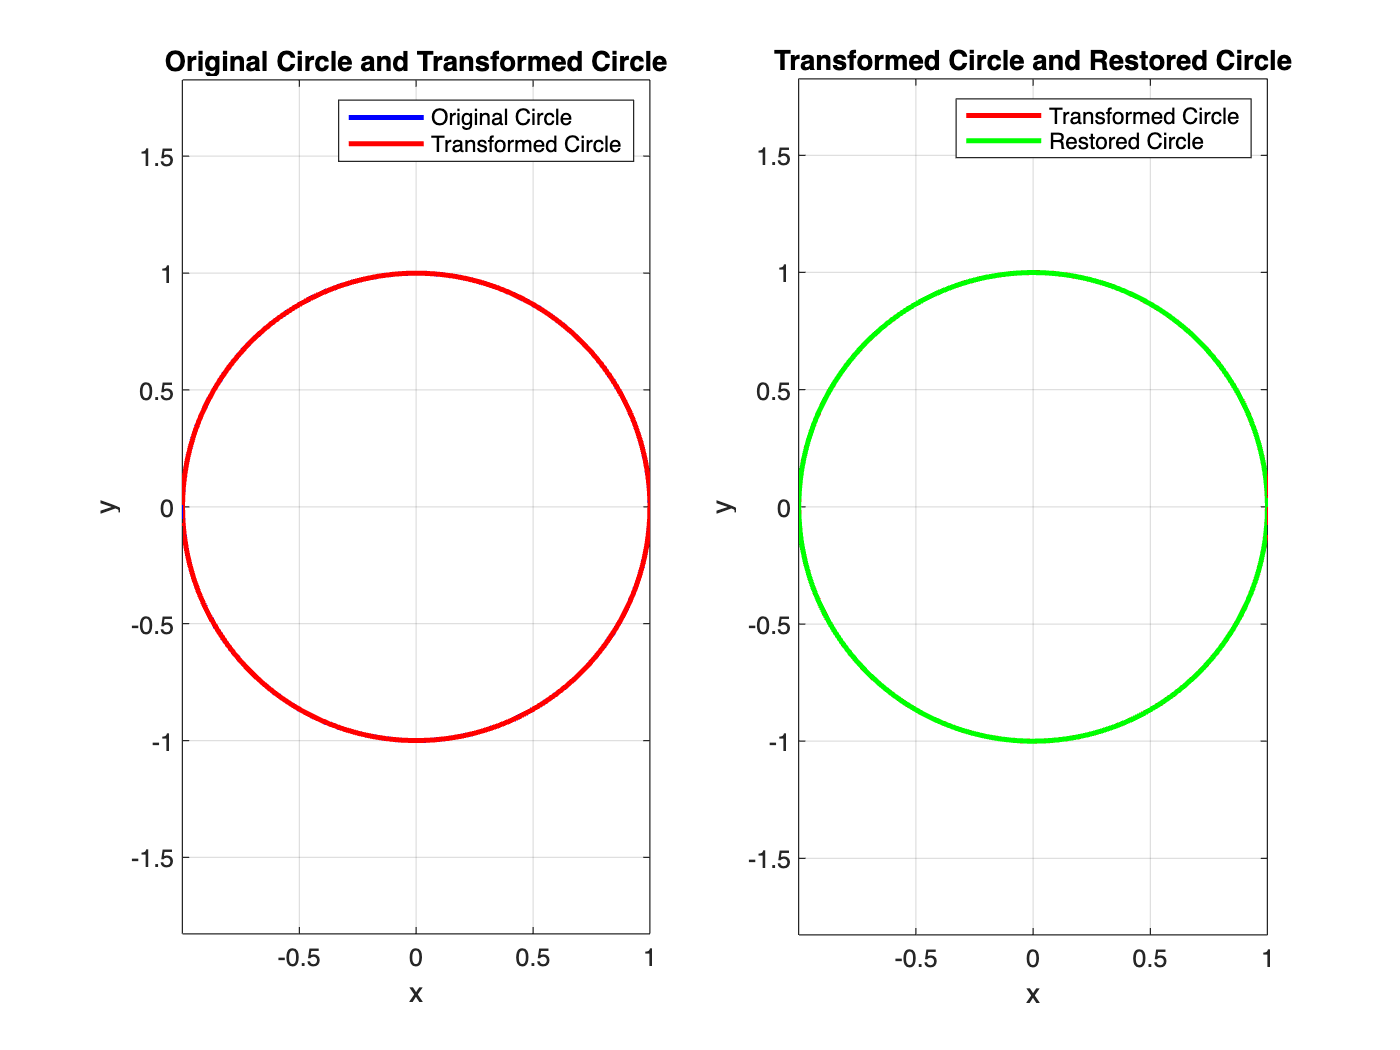


% Visualization
figure;
subplot(1, 2, 1);
plot(circle_points(1,:), circle_points(2,:), 'b-', 'LineWidth', 2);
hold on;
plot(transformed_points(1,:), transformed_points(2,:), 'r-', 'LineWidth', 2);
axis equal;
xlabel('x');
ylabel('y');
title('Original Circle and Transformed Circle');
legend('Original Circle', 'Transformed Circle');
grid on;

% Apply inverse transformation to transformed points
restored_points = T_inv * transformed_points;

subplot(1, 2, 2);
plot(transformed_points(1,:), transformed_points(2,:), 'r-', 'LineWidth', 2);
hold on;
plot(restored_points(1,:), restored_points(2,:), 'g-', 'LineWidth', 2);
axis equal;
xlabel('x');
ylabel('y');
title('Transformed Circle and Restored Circle');
legend('Transformed Circle', 'Restored Circle');
grid on;


% %% Section 7: Computational Challenges
% 
% %% Problem 7.1: Matrix Creation with Specified Rank
% % Write the steps to create a 4×6 matrix with rank 3. Explain your approach.
% 
% % Clear workspace
% clear;
% 
% % Create a 4×6 matrix with rank 3
% % Approach: Multiply a 4×3 matrix by a 3×6 matrix
% A = % Your code here
% B = % Your code here
% C = A * B;
% 
% % Check the rank of the created matrix
% rank_C = rank(C);
% 
% % Display results
% disp('4×6 Matrix C with rank 3:'); disp(C);
% disp('Rank of C = '); disp(rank_C);
% disp('Explanation of approach:');
% disp('I created a 4×6 matrix with rank 3 by multiplying a 4×3 matrix with a 3×6 matrix.');
% disp('The rank of the product cannot exceed the minimum of the ranks of the factors.');
% disp('Since both factor matrices have full rank 3, the product has rank 3.');

% 
% %% Problem 7.2: Geometric Transformation
% % Define a transformation matrix T = [cos(π/4), -sin(π/4); sin(π/4), cos(π/4)].
% % a) What geometric transformation does this matrix represent?
% % b) Apply this transformation to the points on a unit circle and describe the result.
% % c) Find the inverse transformation T⁻¹ and explain its geometric meaning.
% 
% % Clear workspace
% clear;
% 
% % Define the transformation matrix T
% angle = pi/4;  % 45 degrees
% T = [cos(angle), -sin(angle); sin(angle), cos(angle)];
% 
% % a) Identify the geometric transformation
% disp('a) This transformation matrix represents a rotation by 45 degrees counterclockwise.');
% 
% % b) Apply the transformation to points on a unit circle
% theta = linspace(0, 2*pi, 100);
% circle_points = [cos(theta); sin(theta)];
% transformed_points = % Your code here
% 
% % c) Find the inverse transformation and explain its meaning
% T_inv = % Your code here
% 
% % Explanation
% disp('c) The inverse transformation matrix represents a rotation by -45 degrees');
% disp('   (or 45 degrees clockwise), which undoes the original transformation.');
% 
% % Visualization
% figure;
% subplot(1, 2, 1);
% plot(circle_points(1,:), circle_points(2,:), 'b-', 'LineWidth', 2);
% hold on;
% plot(transformed_points(1,:), transformed_points(2,:), 'r-', 'LineWidth', 2);
% axis equal;
% xlabel('x');
% ylabel('y');
% title('Original Circle and Transformed Circle');
% legend('Original Circle', 'Transformed Circle');
% grid on;
% 
% % Apply inverse transformation to transformed points
% restored_points = T_inv * transformed_points;
% 
% subplot(1, 2, 2);
% plot(transformed_points(1,:), transformed_points(2,:), 'r-', 'LineWidth', 2);
% hold on;
% plot(restored_points(1,:), restored_points(2,:), 'g-', 'LineWidth', 2);
% axis equal;
% xlabel('x');
% ylabel('y');
% title('Transformed Circle and Restored Circle');
% legend('Transformed Circle', 'Restored Circle');
% grid on;